load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29


sum(sum(ismissing(HCV)))

ans = 0

cdata=table2array(HCV);
[out_array,tf]=rmoutliers(cdata(:,[1,3,11:end]));
for i=1:1385
    if tf(i)==1
        cdata(i,:)=[];
    end
end

[corr(cdata(:,1:27),cdata(:,29),'type',"Spearman") corr(cdata(:,1:27),cdata(:,29),'type',"Pearson") corr(cdata(:,1:27),cdata(:,29),'type',"Kendall")]

ans =    -0.0187   -0.0185   -0.0142
    0.0096    0.0100    0.0088
   -0.0576   -0.0565   -0.0447
   -0.0301   -0.0298   -0.0275
    0.0548    0.0550    0.0500
   -0.0025   -0.0027   -0.0023
   -0.0072   -0.0076   -0.0066
    0.0139    0.0139    0.0127
    0.0195    0.0197    0.0178
   -0.0515   -0.0522   -0.0470


x=cdata(:,1:27);
y=cdata(:,29);
[Xtrain,Ytrain,Xtest,Ytest]=trainTestSplit(x,y,0.7);
Xztrain=zscore(Xtrain);
Xztest=zscore(Xtest);
Yztrain=zscore(Ytrain);
Yztest=zscore(Ytest);

# Linear Regression with Intercept

b_lr1=regress(Ytrain,Xtrain)

b_lr1 =    -0.0002
    0.0489
    0.0018
   -0.0676
    0.1175
    0.0401
   -0.0670
    0.0456
    0.0347
   -0.0944


pred_lr1=round(Xtest*b_lr1)

pred_lr1 =      2
     3
     3
     2
     3
     2
     3
     2
     3
     2


a_lr1=sum(pred_lr1==Ytest)/length(Ytest)

a_lr1 = 0.2609

% b_lr1=regress(Yztrain,Xztrain)

b_lr1 =    -0.0251
    0.0065
   -0.0319
   -0.0483
    0.0411
    0.0066
   -0.0510
    0.0016
   -0.0058
   -0.0605


% pred_lr1=(Xztest*b_lr1)

pred_lr1 =    -0.1356
    0.3416
    0.0783
   -0.2136
    0.0969
   -0.0433
    0.2237
   -0.1938
    0.1493
   -0.1887


% [pred_lr1 Yztest]

ans =    -0.1356    1.2661
    0.3416   -1.3723
    0.0783   -0.4928
   -0.2136   -1.3723
    0.0969    1.2661
   -0.0433   -1.3723
    0.2237    1.2661
   -0.1938   -0.4928
    0.1493   -1.3723
   -0.1887   -1.3723


% a_lr1=sum(pred_lr1==Yztest)/length(Yztest)

a_lr1 = 0

b_lr2=fitlm(Xtrain,Ytrain)

b_lr2 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)         2.8466       0.81332         3.5    0.00048716
    x1              -0.0031934     0.0041472    -0.77001       0.44149
    x2                0.014534      0.072852      0.1995       0.84192
    x3               -0.008724     0.0089346    -0.97643        0.3291
    x4                 -0.1077       0.07239     -1.4877       0.13716
    x5                0.091654      0.07320

pred_lr2=round(predict(b_lr2,Xtest))

pred_lr2 =      2
     3
     3
     2
     3
     2
     3
     2
     3
     2


a_lr2=sum(pred_lr2==Ytest)/length(Ytest)

a_lr2 = 0.2512

% b_lr2=fitlm(Xztrain,Yztrain)

b_lr2 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27

Estimated Coefficients:
                    Estimate        SE         tStat        pValue 
                   __________    ________    __________    ________

    (Intercept)    2.4779e-16    0.032202    7.6949e-15           1
    x1              -0.025068    0.032556      -0.77001     0.44149
    x2              0.0065115     0.03264        0.1995     0.84192
    x3              -0.031925    0.032695      -0.97643      0.3291
    x4              -0.048265    0.032442       -1.4877     0.13716
    x5               0.041071    0.032802        1.2521     0.21

% pred_lr2=round(predict(b_lr2,Xztest))

pred_lr2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% a_lr2=sum(pred_lr2==Yztest)/length(Yztest)

a_lr2 = 0

b_lr3=mnrfit(Xtrain,categorical(Ytrain))

b_lr3 =     0.9627   -2.6863   -0.4062
    0.0153    0.0219    0.0108
    0.0635   -0.3297    0.0855
    0.0175    0.0607    0.0310
    0.0876    0.3152    0.2942
   -0.3507   -0.2024   -0.0876
    0.2976    0.1093    0.0946
    0.0499    0.0424   -0.0212
   -0.0841    0.0918    0.0211
   -0.1713    0.1791   -0.1084


pred_lr3=mnrval(b_lr3,Xtest)
%a_lr3=sum(round(pred_lr3(:,2))==Ytest)/length(Ytest)

a_lr3 = 0

b_lr3=mnrfit(Xztrain,categorical(Yztrain))
pred_lr3=mnrval(b_lr3,Xztest)

# Lasso Regression

[b_lasso, fit_lasso]=lasso(Xtrain,Ytrain,"CV",5)

b_lasso =    -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0032   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031   -0.0031
    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0144    0.0143    0.0143    0.0143    0.0143    0.0143    0.0142    0.0142    0.0142    0.0141    0.0141    0.0140    0.0140    0.0139    0.0139    0.0138    0.0138    0.0137    0.0136    0.0135    0.013

fit_lasso = struct with fields:
         Intercept: [1×100 double]
            Lambda: [1×100 double]
             Alpha: 1
                DF: [1×100 double]
               MSE: [1×100 double]
    PredictorNames: {}
                SE: [1×100 double]
      LambdaMinMSE: 0.0607
         Lambda1SE: 0.0607
       IndexMinMSE: 100
          Index1SE: 100


b_l1=b_lasso(:,fit_lasso.IndexMinMSE)

b_l1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


b_l2=b_lasso(:,fit_lasso.Index1SE)

b_l2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


pred_l1=Xtest*b_lasso(:,1) + fit_lasso.Intercept(fit_lasso.IndexMinMSE)

pred_l1 =     2.0450
    2.5798
    2.2846
    1.9655
    2.2995
    2.1601
    2.4571
    1.9934
    2.3706
    1.9842


a_l1=sum(round(pred_l1)==Ytest)/length(Ytest)

a_l1 = 0.2246

b_lasso =    -0.0251   -0.0251   -0.0251   -0.0251   -0.0251   -0.0251   -0.0251   -0.0251   -0.0251   -0.0251   -0.0251   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0250   -0.0249   -0.0249   -0.0249   -0.0249   -0.0249   -0.0249   -0.0249   -0.0248   -0.0248   -0.0248   -0.0248   -0.0247   -0.0247   -0.0247   -0.0246   -0.0246   -0.0245   -0.0245   -0.0244
    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0063    0.0063    0.0063    0.0063    0.0063    0.0062    0.0062    0.0062    0.0062    0.0061    0.0061    0.0061    0.006

fit_lasso = struct with fields:
         Intercept: [1×100 double]
            Lambda: [1×100 double]
             Alpha: 1
                DF: [1×100 double]
               MSE: [1×100 double]
    PredictorNames: {}
                SE: [1×100 double]
      LambdaMinMSE: 0.0544
         Lambda1SE: 0.0544
       IndexMinMSE: 100
          Index1SE: 100


b_l1 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


b_l2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


pred_l1 = 	1.0e+05 *

    0.4776
    0.7351
    0.6219
    0.4182
    0.6077
    0.7531
    0.6567
    0.3258
    0.7210
    0.6434


a_l1 = 0

# Stepwisefit

[b_step,~,~,inmodel]=stepwisefit(Xtrain,Ytrain)

Initial columns included: none
Step 1, added column 5, p=0.0427272
Final columns included:  5 
    'Coeff'          'Std.Err.'      'Status'    'P'     
    [    -0.0065]    [    0.0041]    'Out'       [0.1130]
    [     0.0336]    [    0.0725]    'Out'       [0.6432]
    [    -0.0117]    [    0.0088]    'Out'       [0.1847]
    [    -0.0411]    [    0.0726]    'Out'       [0.5711]
    [     0.1471]    [    0.0725]    'In'        [0.0427]
    [    -0.1256]    [    0.0724]    'Out'       [0.0831]
    [    -0.0320]    [    0.0725]    'Out'       [0.6589]
    [     0.0363]    [    0.0725]    'Out'       [0.6168]
    [     0.0269]    [    0.0725]    'Out'       [0.7105]
    [    -0.0900]    [    0.0725]    'Out'       [0.2148]
    [ 2.2169e-05]    [1.3779e-05]    'Out'       [0.1080]
    [ 1.2131e-07]    [1.0514e-07]    'Out'       [0.2489]
    [     0.0026]    [    0.0212]    'Out'       [0.9014]
    [-8.7494e-07]    [9.4789e-07]    'Out'       [0.3562]
    [    -0.0013]    [    0.0014]  

b_step =    -0.0065
    0.0336
   -0.0117
   -0.0411
    0.1471
   -0.1256
   -0.0320
    0.0363
    0.0269
   -0.0900


inmodel = 1×27 logical array
   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


HCV.Properties.VariableNames(inmodel);
b_step(~inmodel)=0;
pred_step=Xtest*b_step

pred_step =     0.1471
    0.1471
    0.2941
    0.1471
    0.1471
    0.1471
    0.1471
    0.2941
    0.2941
    0.1471


a_step=sum(round(pred_step)==Ytest)/length(Ytest)

a_step = 0

# PLS Regression

[~,~,~,~,~,~,PLS_mse]=plsregress(Xtrain,Ytrain,6,'cv',3)

PLS_mse = 	1.0e+11 *

    6.0822    4.8290    4.1086    3.1856    2.0582    1.4863    1.2645
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


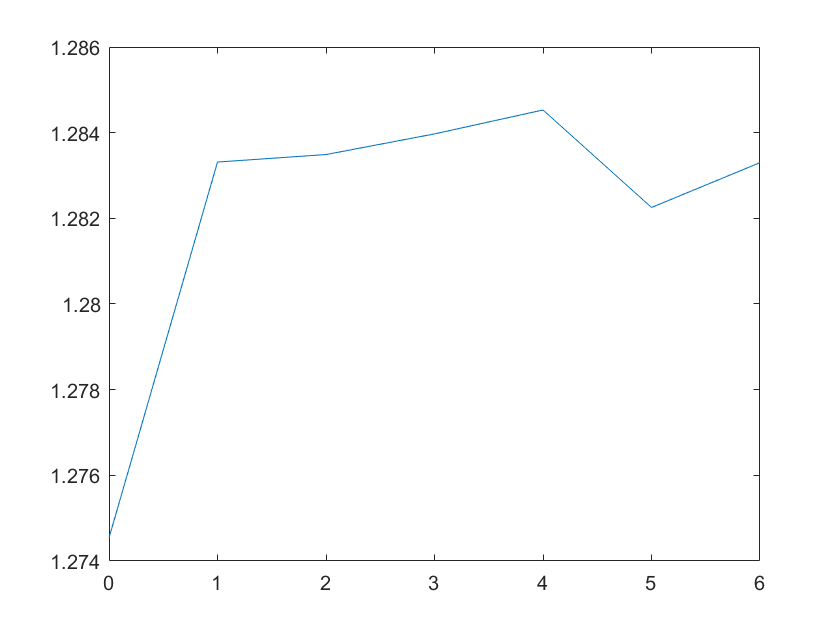

Xztrain =     0.8704    1.0214   -0.8922   -1.0515    0.9923    1.0047   -0.9882    0.9984   -1.0151   -0.9882    1.3650    1.1669   -1.5238    0.7394   -1.2393   -1.7555    0.7545    1.6861    0.6876    0.9468    0.8317    1.2077    0.4865   -0.5677   -0.9811   -1.0789   -1.0854
    1.6673   -0.9780   -0.1637    0.9501    0.9923    1.0047    1.0109   -1.0005   -1.0151   -0.9882   -1.5159   -0.8813    0.2311   -0.2470    0.0996    1.4934    0.1459   -1.5432    0.1496    0.4960    1.4826    1.3491   -0.0503   -0.1958   -0.8802   -0.3932    1.7932
   -0.8375    1.0214    1.5361   -1.0515   -1.0067    1.0047   -0.9882    0.9984   -1.0151    1.0109   -1.2523    1.2858    0.2311    0.8105   -1.1245   -1.3250   -1.2995    1.3062   -0.7341    1.5102   -1.6955   -1.0553    0.3138    0.0483   -0.4853    0.5441   -0.3620
   -1.1791    1.0214   -1.3779   -1.0515    0.9923   -0.9943    1.0109   -1.0005    0.9841   -0.9882   -0.0983    0.1299   -1.5238   -0.2643   -0.2064   -1.1292    1.6674    0.8

plot(0:6,PLS_mse(2,:))

[~,~,~,~,~,~,PLS_mse]=plsregress(Xztrain,Yztrain,27,'cv',3)

PLS_mse =    27.0459   26.1308   24.9447   23.5728   22.6126   21.7118   20.7751   19.7468   18.7962   17.9664   17.0849   16.0860   15.1022   14.0639   13.1089   12.1249   11.0828   10.0606    9.0127    7.9498    6.9463    5.9736    4.9849    4.0137    2.9788    1.8941    0.9555    0.0000
    0.9996    1.0282    1.0258    1.0260    1.0262    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263    1.0263


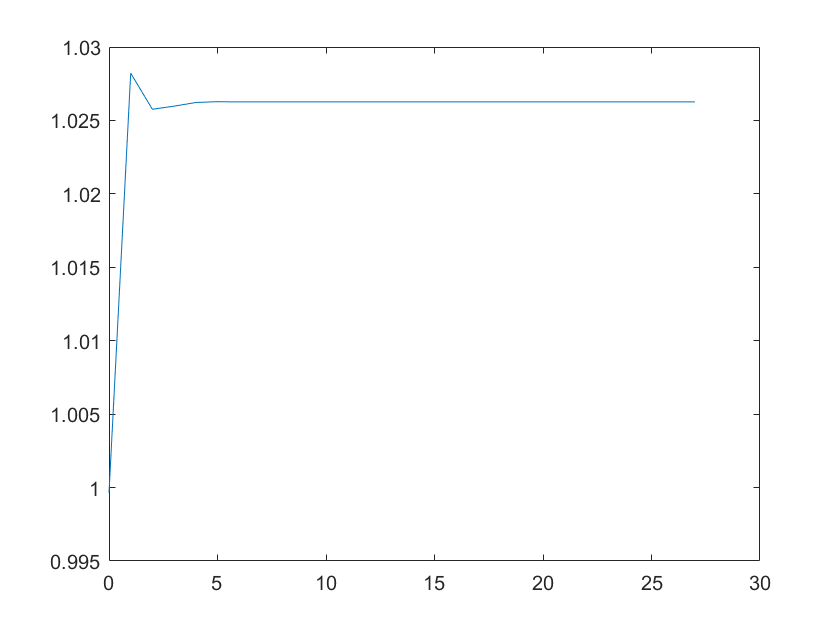

plot(0:27,PLS_mse(2,:))

# Neural Networks

net=fitnet(10,'trainbr');
net=train(net,Xtrain',Ytrain');
y=net(Xtest');
perf = perform(net,y,Ytest')

perf = 1.2993

sum(round(y')==Ytest)/length(Ytest)

ans = 0.2560

net=fitnet(10);
net=train(net,Xtrain',Ytrain');
y=net(Xtest');
perf = perform(net,y,Ytest')

perf = 1.3430

sum(round(y')==Ytest)/length(Ytest)

ans = 0.2343

net=fitnet(10,'traingd');
net=train(net,Xtrain',Ytrain');
y=net(Xtest');
perf = perform(net,y,Ytest')

perf = 1.4477

sum(round(y')==Ytest)/length(Ytest)

ans = 0.2657

net=fitnet(10,'traingdm');
net=train(net,Xtrain',Ytrain');
y=net(Xtest');
perf = perform(net,y,Ytest')

perf = 1.6770

sum(round(y')==Ytest)/length(Ytest)

ans = 0.2005